# Esophageal Biomechanical Analysis - Work, Power, and Modulus

% Project Team: Melissa Ledgerwood, Zihao Kong, Kelvin Mo, Moriah Jewett,
% Ryan Farzaneh

% Description:
% This sript is intended to be used with Medtronic/Given high resolution impedance
% manometry data. The data input is a text file incapturing single swallow with a 30sec frame.
% The text file is organized such that the first columns are the pressure
% data, the next set is the impedance data.  The rows are by time.  

% One of the novel things about this code is the implimentation of a time
% delay on the pressure to time align the pressure and imepdance sensors.
% The reason for this is because the sensors are not spacially aligned.
% The bolus first hits the pressure sensor before contacting the impedance
% sensor.  We approximate the speed of the bolus from imp sensor 7 to 14 by tracking the
% min imp value (Nadir). We find out how much time the bolus would take to travel 2 cm then, 
% adjust the time accordingly.

% Work is calculated as the area under the Tension-Area curve.  Power is Work/time. 
% Idealy we would calculate the power based on the time of swallow duration,
% but given that we don't know how to track a landmark of peristalsis
% termination, we decided for simplicity that we would use a standardized time to evaluate 
% all the subjects (patients & normals). The time interval used is 30sec.

% The modulus of distension is a novel parameter presented here, which is the slope of the 
% distension line on the Tension-Area plot.  This is taken from the starting point just before 
% bolus entry to peak distension. We liken to a stress-strain curve modulus because stress and strain are built into variable.  
% This modulus we feel represents the stiffness of the tissue.  This may be
% an important parameter evaluating patient disease because their tissue stiffness maybe different.


clear

SwallowID = "EsoEMG_Martinez_WS5_30sec.txt"

SwallowID = "EsoEMG_Martinez_WS5_30sec.txt"

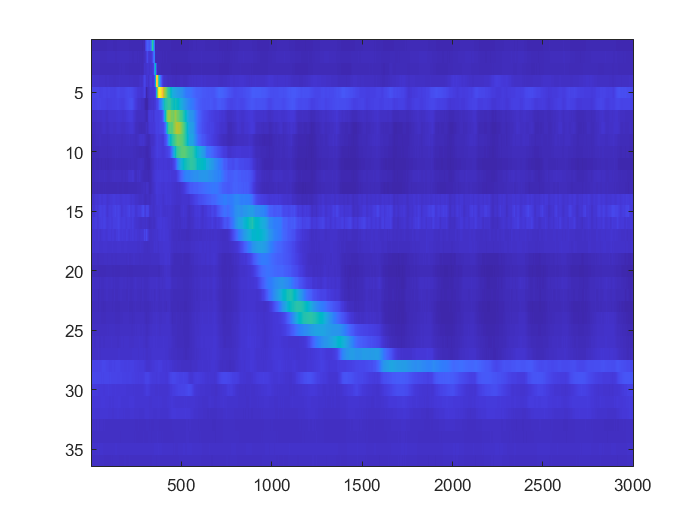

mat = readmatrix(SwallowID);
mat = mat(2:end,2:end);

rawpressure = mat(:, 1:36);
impedance = mat (:,37:end);

figure, imagesc(rawpressure')

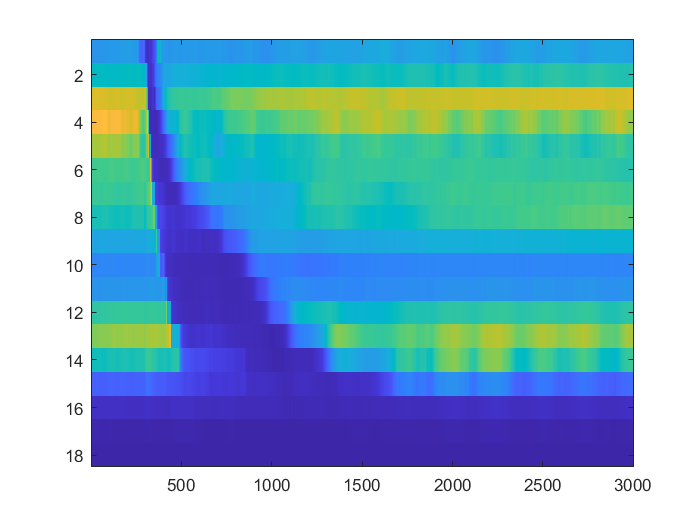

figure, imagesc(impedance')


%% To find the velocity of distal peristalsis to determine the time delay to
% use.

% Read & index imp sensor #7 and find the nadir impedance value (min)
min_imp7 = min(impedance(:,7));
start_unit7 = find(impedance(:,7) == min_imp7);
start_unit7 = start_unit7(1,:);

% % If needed, use the maximal impedance value (air) instead 
% max_imp7 = max(impedance(:,7))
% start_unit7 = find(impedance(:,7) == max_imp7)
% start_unit7 = start_unit7(1,:)

% Read & index imp sensor #14 and find the nadir impedance value (min)
min_imp14 = min(impedance(:,14));
start_unit14 = find(impedance(:,14) == min_imp14);
start_unit14 = start_unit14(end,:);

time = (start_unit14 - start_unit7)*0.01; % converts to seconds
distance = 8 * 2; % distance between the top and bottom sensors
velocity = distance / time % cm/sec <--PRINT!!!!! x

velocity = 2.7073


% time delay for P23 is to shift it by about 2cm 
timedelay = 2./velocity % 2cm / (sec/cm)

timedelay = 0.7388

fudge_factor = 0.0 * timedelay % currently set to zero but can be up to 50% time delay

fudge_factor = 0

timedelay = fudge_factor + timedelay

timedelay = 0.7388

sample_rate = 0.01;

%% Prep data
% Impedance channel #12 -column #48 (#1 is in the proximal)
% impedance channel  = 36 pressure + impedance channel of choise
impedance = mat(:,48);
%plot (impedance)
%title("Impedance data over time")

% Pressure Data sensor #23 
rawpressure = mat(:,23);
rawpressure = rawpressure(~isnan(rawpressure))';

% View pressure spectrum
% pressure_frequency = fftshift(fft(rawpressure));
% time_in_half = linspace(0,1,floor(length(rawpressure)/2));
% pressure_in_half = abs(fft(rawpressure));
% pressure_in_half = pressure_in_half(1:floor((length(rawpressure)/2)));
% figure
% plot(time_in_half,pressure_in_half);
% title("pressure in frequency 0 to 1 scale")

% Apply Butterworth filter to pressure.  The limits were set based on
% pressure spectrum.
[b,a] = butter(2,0.0075,"low");
filtered_pressure = filter(b,a,rawpressure);

% Comparison of the filtered to raw pressure data.
% figure
% plot((1:length(rawpressure)),rawpressure)
% title("pressure unfiltered")
% plot((1:length(filtered_pressure)),filtered_pressure)
% title("pressure filtered")

% This section is to trim time off of the data.  200 data pts is 2 seconds.
% The time per data pt is 0.01 sec. You would do this if the data in the frame is too long.
% This is important when calculating Power because it is dependent on time.
% filtered_pressure = filtered_pressure (1:end-1100);
% impedance = impedance (1:end-1100);


% Unit conversion - to convert mmHg to N/mm^2
pressure_converted = transpose(0.000133322.*filtered_pressure); %mmHg
area = (28.502*(1./impedance(1:length(pressure_converted))))+ 1.2028; %mm2
%area= 23256*(1./(impedance.*1000)) % Pouillet's Law
radius = sqrt(area/pi);

% Tension Strain w/o time delay.  
tension = (pressure_converted.*radius); %[(N/mm2)*mm]
tension_converted = tension.*1000; %1000 mm/m = N/m
strain = (radius-radius(1))/radius(1); %no units

% % Wrap around to complete loops
tension(end+1) = tension(1,:);
tension_converted(end+1) = tension_converted(1,:);
area (end+1) = area(1,:);
strain (end+1) = strain(1,:);

% Calculate Work & Power
Work = polyarea(area, tension)  % Work is tension (N/m) over area (mm2), units of Joules = N*m 

Work = 0.8412

time = length (tension) * 0.01 % units of seconds. 0.01 centisec per data point.

time = 30.0100

Power = Work/time % Units of Watts

Power = 0.0280

% add time delay - delay time pressure/impedance forward
impdelay = transpose(impedance((1/sample_rate*timedelay):length(filtered_pressure)));% impedance data with delay

pressure_converted = 0.000133322.*filtered_pressure; % mmHg -> N/mm2 
Max_Pressure = max(filtered_pressure); % mmHg % <--PRINT Max Pressure
press_delay = pressure_converted (1:length(impdelay));
[Nadir_impedance,index_n] = min (impdelay) % <--PRINT Nadir Impedance

Nadir_impedance = 0.1620

index_n = 676

PreBaselineImp = impdelay(1) % <--PRINT Baseline Imp before swallow

PreBaselineImp = 2.3200

PostBaselineImp = impdelay(end)

PostBaselineImp = 2.3060

BaselinePressure = filtered_pressure(1)

BaselinePressure = 6.4843e-04



% area = (28.502*(1./impedance(1:length(pressure_converted))))+ 1.2028; %mm2
areae = (28.502*(1./impdelay))+ 1.2028; % empirical data trendline from gel supine
% areap= 23256*(1./(impedance.*1000))
radiuse = sqrt(areae/pi);

% Biomechanical Analysis
tension_delay = (press_delay.*radiuse); %[(N/mm2)*mm]
tensionunitsd = tension_delay.*1000; %1000mm/m = N/m
straine = (radiuse-radiuse(1))/radiuse(1); %no units

% Wrap around to complete loops
tension_delay(end+1) = tension_delay(:,1);
tensionunitsd(end+1) = tensionunitsd (:,1);
areae (end+1) = areae(:,1);
straine (end+1) = straine(:,1);

% Work & Power Analysis
wrap_Workd = polyarea(areae,tension_delay)  % Work is tension (N/m) over area (mm2), units of Joules = N*m <--PRINT x

wrap_Workd = 0.3659

wrap_Powerd = wrap_Workd/time % Units of Watts <--PRINT x

wrap_Powerd = 0.0122

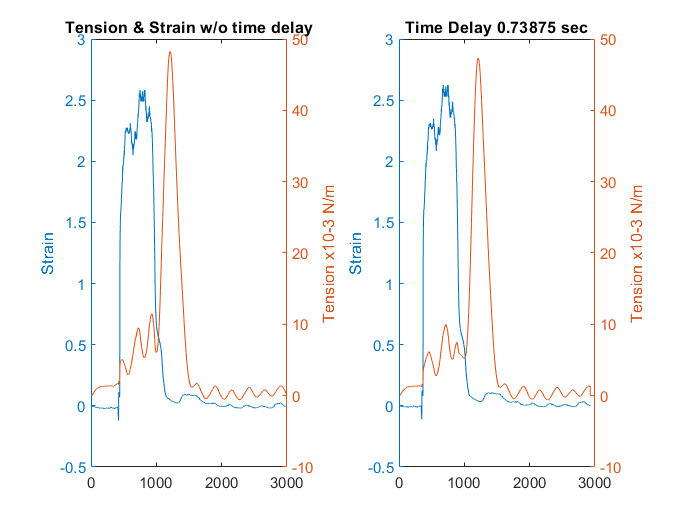



% Tension-Strain plots w/ & w/o time delay
figure
subplot (1,2,1)
yyaxis right
plot (tension_converted)
ylabel('Tension x10-3 N/m')
yyaxis left
plot (strain)
ylabel('Strain')
title ('Tension & Strain w/o time delay')

subplot (1,2,2)
yyaxis right
plot (tensionunitsd)
ylabel('Tension x10-3 N/m')
yyaxis left
plot (straine)
ylabel('Strain')
%title ('Tension & Strain w/ time delay')
txt1 = ['Time Delay ' num2str(timedelay) ' sec'];
title(txt1)

% Variables

% Based on Tension-Area graph
[max_area, index_sa] = max(area); 
[min_area, index_s_ma] = min(area);

max_tension_during_distension = tension_converted(index_sa) % <--PRINT max tenstion during distension x (N/m)

max_tension_during_distension = 8.8240

max_tension_during_distension_units = tension(index_sa) % N/mm

max_tension_during_distension_units = 0.0088

min_tension_during_distension = tension_converted (index_s_ma) % <-- PRINT min tension x % removed tensionunitsd

min_tension_during_distension = 1.5880

min_tension_during_distension_units = tension(index_s_ma)

min_tension_during_distension_units = 0.0016


modulus_of_distension = (max_tension_during_distension - tension(1))/(max_area-area(1)) % <--PRINT modulus based on tension-area curve

modulus_of_distension = 0.0540

modulus_of_closure = (max_tension_during_distension - min_tension_during_distension)/(max_area-min_area) % <--PRINT modulus based on tension-area curve

modulus_of_closure = 0.0435


% Modulus with time delay
[max_areae, index_sae] = max(areae);
[min_areae, index_s_mae] = min(areae);

max_tension_during_distensiondunits = tensionunitsd(index_sae) %N/m

max_tension_during_distensiondunits = 8.6451

max_tension_during_distensiond = tension_delay(index_sae) %N/mm

max_tension_during_distensiond = 0.0086


min_tension_during_distensiond = tensionunitsd(index_s_mae)

min_tension_during_distensiond = 1.2133

min_tension_during_distensiond = tension_delay(index_s_mae)

min_tension_during_distensiond = 0.0012


modulus_of_distensiond = (max_tension_during_distensiond - tension_delay(1))/(max_areae-areae(1)) % <--PRINT modulus based on tension-area curve

modulus_of_distensiond = 5.2825e-05


% Based on Tension-Strain graph
[max_strain, index_s] = max(strain); 
[min_strain, index_s_m] = min(strain);

max_tension_during_distension_s = tension_converted(index_s) 

max_tension_during_distension_s = 8.8240

min_tension_during_distension_s = tension_converted(index_s_m) 

min_tension_during_distension_s = 1.5880


modulus_of_distension_TS= (max_tension_during_distension_s - tension_converted(1))/(max_strain-strain(1)) % <--PRINT modulus based on tension-strain curve

modulus_of_distension_TS = 3.4150

modulus_of_closure_TS = (max_tension_during_distension_s - min_tension_during_distension_s)/(max_strain-min_strain) % <--PRINT modulus based on tension-strain curve

modulus_of_closure_TS = 2.6765


[max_tension,index_t] = max(tension_converted) % <--PRINT max_tension

max_tension = 48.2720

index_t = 1212

strain_point_at_max_tension = strain(index_t)

strain_point_at_max_tension = 0.0480


% set window to select from contraction phase.
left_window = 600;
right_window = 900;

[local_min_strain,offset] = min(strain(left_window:right_window));
tension_at_local_min = tensionunitsd(left_window+offset);

modulus_of_contraction = (max_tension-tension_at_local_min) / (strain_point_at_max_tension-local_min_strain) % <--PRINT x

modulus_of_contraction = -20.9360

max_area = max(area) % <--PRINT 

max_area = 177.1411

intrabolus_pressure = filtered_pressure (index_n) % <-- PRINT x

intrabolus_pressure = 8.6355

Distensibility = max_area/intrabolus_pressure % <-- PRINT x

Distensibility = 20.5132

max_radius = max(radius);

PostBaselineImp = impdelay(end)

PostBaselineImp = 2.3060

BaselinePressure = filtered_pressure(1)

BaselinePressure = 6.4843e-04

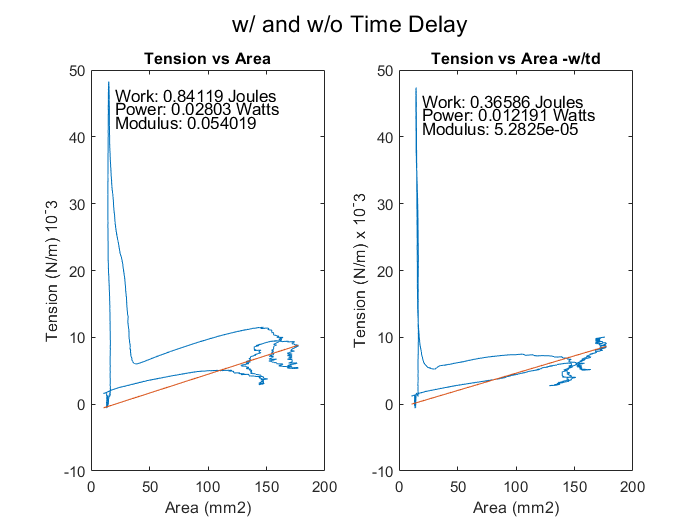


% Work-loop w/ & w/o time delay
figure
sgtitle ('w/ and w/o Time Delay')

% Tension-Area plot without a time delay
subplot (1,2,1)
plot(area,tension_converted)
title ('Tension vs Area')
xlabel('Area (mm2)')
ylabel('Tension (N/m) 10^-3')
txt1 = ['Work: ' num2str(Work) ' Joules'];
[ypos, xpos] = max(tension_converted); 
text(area(xpos) + 5, ypos - 2, txt1) 
txt2 = ['Power: ' num2str(Power) ' Watts'];
text(area(xpos) + 5, ypos - 4, txt2) 
txt3 = ['Modulus: ' num2str(modulus_of_distension) ];
hold on
plot([min_area max_area],[min(tension_converted) max_tension_during_distension])
text(area(xpos) + 5, ypos - 6, txt3)
hold off

% Tension-Area with the time delay
subplot (1,2,2)
plot(areae,tensionunitsd)
title ('Tension vs Area -w/td')
xlabel('Area (mm2)')
ylabel('Tension (N/m) x 10^-3') %<--how do I get a superscript?
txt1 = ['Work: ' num2str(wrap_Workd) ' Joules'];
[ypos, xpos] = max(tensionunitsd);
text(areae(xpos) + 5, ypos - 2, txt1) 
txt2 = ['Power: ' num2str(wrap_Powerd) ' Watts'];
text(areae(xpos) + 5, ypos - 4, txt2) 
txt3 = ['Modulus: ' num2str(modulus_of_distensiond) ];
hold on
plot([min(areae) max(areae)],[min_tension_during_distensiond max_tension_during_distensiondunits])
text(areae(xpos) + 5, ypos - 6, txt3)
hold off

DataNames = {"Swallow ID",'Work','Work td', 'Power', 'Power td','Modulus of Distension','Modulus of Distension td','Distensibility (A/P)','Max Pressure', 'Intrabolus Pressure', 'Nadir Impedance', 'Max area', 'Max Tension -contraction', 'Max Tension -distension', 'Min Tension', 'Max Strain', 'Modulus of Closure', 'Modulus of contraction', 'Pre-Baseline Impedance', 'Post-Baseline Impedance', 'Baseline Pressure','Distal Velocity'};
Data = {SwallowID, Work, wrap_Workd, Power, wrap_Powerd, modulus_of_distension, modulus_of_distensiond, Distensibility, Max_Pressure, intrabolus_pressure, Nadir_impedance, max_area, max_tension, max_tension_during_distension, min_tension_during_distension, max_strain, modulus_of_closure, modulus_of_contraction, PreBaselineImp, PostBaselineImp, BaselinePressure, velocity};
T = table([DataNames;Data])

T = 2×1 table
       Var1    
    ___________

    {1×22 cell}
    {1×22 cell}


writetable(T,"EsoEMG_Martinez_WS5_30sec.xls") % change the name here to change the file name



%% Assessing the need for a time delay.  This code would go after the pressure data is filtered. 
% figure
% sgtitle ('Does pressure signal need to be pushed back in time?')
% subplot (2,1,1)
% yyaxis left
% plot (impedance)
% ylabel('Impedance kOhms')

% yyaxis right
% plot (rawpressure)
% ylabel('Pressure mmHg')
% legend('impedance','pressure')
% title ('Unfiltered Pressure & Impedance')

%subplot (2,1,2)
% figure 
% yyaxis left
% plot (impedance)
% ylabel('Impedance kOhms')
% 
% yyaxis right
% plot (filtered_pressure)
% ylabel('Pressure mmHg')
% title ('Filtered Pressure & Impedance')